# Labor 7: Regler III

## Einleitung

In dieser Übung wird eine vorgegebene Strecke mit einem PID-Regler geregelt.  

Ein PID-Regler tritt meist entweder in additiver (paralleler) oder in multiplikativer (serieller) Form auf. Für die parallele Form wird meist zwischen zwei Schaltungsalternativen unterschieden: zum Einen mit P-, I- und D-Glied (Abbildung links) 


$$G_{\mathrm{r}} \left(s\right)=K_{\mathrm{P}} +\frac{K_{\mathrm{I}} }{s}+K_{\mathrm{D}} \cdot s$$


und zum Anderen mit Zeitkonstanten (Abbildung rechts)

$G_{\mathrm{r}} \left(s\right)=K_{\mathrm{P}} \cdot \left(1+\frac{1}{T_{\mathrm{N}} \cdot s}+T_{\mathrm{V}} \cdot s\right)$.

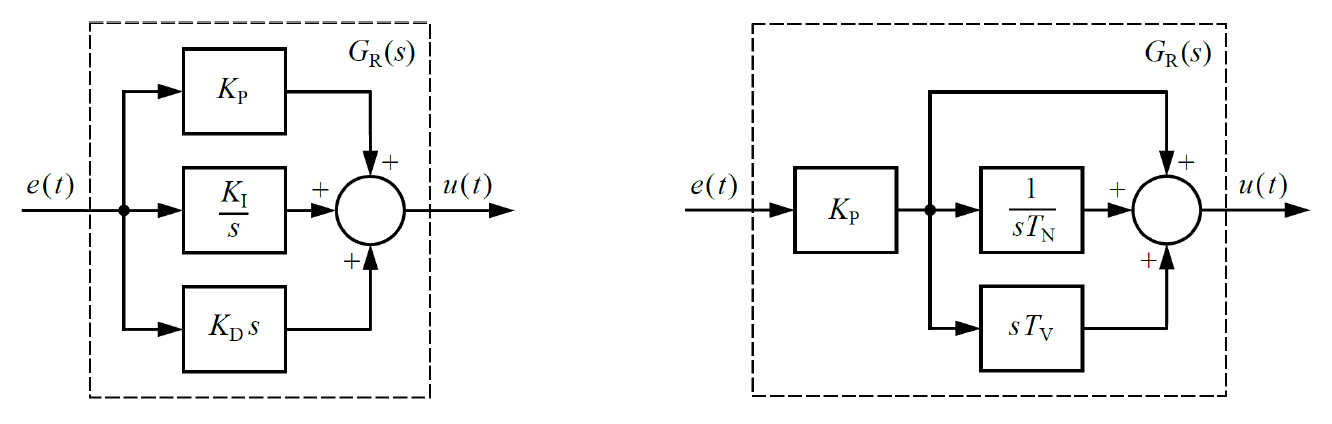

In der Praxis wirken oft Störeinflüsse auf das Regelsystem ein; diese können beispielsweise die Stellgröße verzerren, die zu regelnde Strecke verändern oder die Rückführung (Messung) verfälschen. Eine weitere Herausforderung der Regelungstechnik stellen *Stellgrößenbeschränkungen* dar; sie schränken den gültigen Wertebereich der Stellgröße ein. Es kann z.B. der Eingangsstrom für eine Heizung oder einen Motor nicht beliebig groß sein. Dies entspricht einem Sättigungsverhalten, womit der Regelkreis nicht-linear wird. 

clear variables
clc

## Aufgabenstellung

### A Regler-Einstellung mit Trial-and-Error-Verfahren

Die gegebene Strecke 


$$G_{\mathrm{s}} \left(s\right)=\frac{1}{2+0\ldotp 5\cdot s}\cdot e^{\;-0\ldotp 3\cdot s}$$


ist mit einem PID-Regler zu regeln. Bei dieser Strecke ist eine Totzeit von $T_{\mathrm{t}} =0\ldotp 3\;\mathrm{s}$ vorhanden.

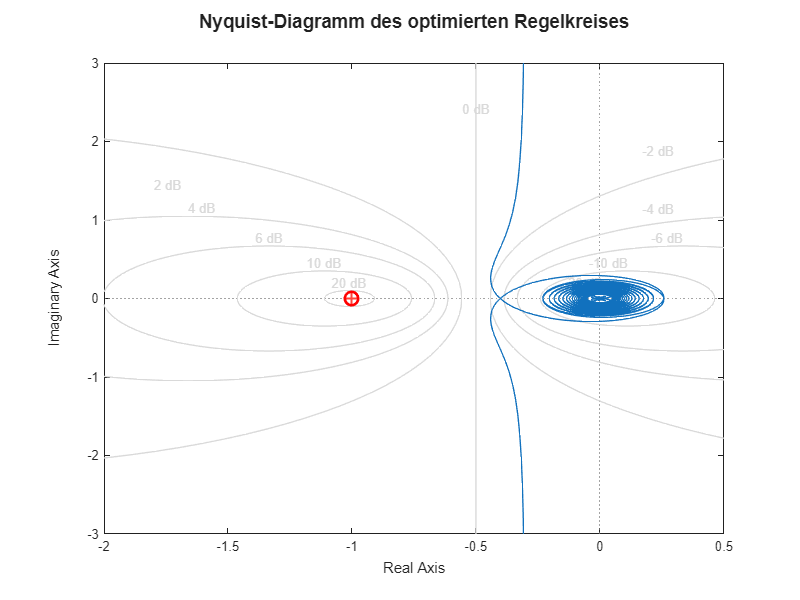

% 1. System-Definition
Gs = tf(1, [0.5, 2], 'inputDelay', 0.3); % Strecke mit 0.3s Totzeit
s = tf('s');

% Regler exakt nach Simulink-Strukturformel definieren
Gr = 1.6 * (1 + (2.5/s) + (0.06 * 100 * s) / (s + 100));
% 3. Offener Regelkreis
Go = Gr * Gs;

% 4. Schöner, hochauflösender Plot
figure('Position', [100, 100, 800, 600]);
% Definiere einen festen Frequenzvektor von 0.1 rad/s bis z.B. 50 rad/s

% Plotten mit begrenztem Frequenzband
nyquist(Go); 
hold on;

% Kritischen Punkt (-1, 0i) fett markieren
plot(-1, 0, 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Kritischer Punkt');

% Achsen-Fokus setzen, damit man das relevante Nyquist-Verhalten sieht!
xlim([-2, 0.5]);
ylim([-3, 3]);

grid on;
grid minor;
title('Nyquist-Diagramm des optimierten Regelkreises', 'FontSize', 14);

Simulieren Sie den Regelkreis in Simulink. Versuchen Sie per Trial-and-Error-Verfahren einen PID-Regler (Simulink-Block `PID Controller`) zu parametrieren, sodass das System möglichst schnell auf einen Eingangssprung reagiert. Wie muss der Regler beschaffen sein, damit bei einem Eingangssprung **keine bleibende Regelabweichung** auftritt? Diskutieren Sie außerdem den jeweiligen Einfluss der P-, I- und D-Glieder.

### B Regler-Einstellung nach Ziegler-Nichols

Entwerfen Sie einen weiteren PID-Regler für die Totzeit-behaftete Regelstrecke aus Aufgabe A. Verwenden Sie dabei das heuristische Verfahren nach Ziegler-Nichols. Für die Regelung eines ${\textrm{PT}}_1$-Glieds in der Form 


$$G\left(s\right)=K\frac{e^{-{s\cdot T}_{\mathrm{t}} } \;}{1+s\cdot T}$$


können die Koeffizienten folgendermaßen bestimmt werden:

$K_{\mathrm{P}} =1\ldotp 2\cdot \frac{T}{K\cdot T_{\mathrm{t}} },\;\;\;T_{\mathrm{N}} =2\cdot T_{\mathrm{t}} ,\;\;\;T_{\mathrm{V}} =0\ldotp 5\cdot T_{\mathrm{t}}$ .

Diese sind in folgende Form zu bringen um die Übertragungsfunktion des PID-Reglers zu bilden:


$$G_{\mathrm{r}} \left(s\right)=K_{\mathrm{P}} \cdot \left(1+\frac{1}{T_{\mathrm{N}} \cdot s}+T_{\mathrm{V}} \cdot s\right)$$


Simulieren Sie auch diesen Regler und vergleichen Sie ihn mit dem Regler aus Aufgabe A anhand von einer Sprungantwort.

%Gs = tf(1, [0.5, 2], 'IoDelay',0.3);%Strecke
s=tf('s');
K=1/2;
T=1/4;
tt=0.3;
Gs = tf(K, [T, 1], 'IoDelay',tt);%Strecke

KP=1.2*T/(K*tt);
TN=2*tt;
TV=0.5*tt;

Gr = pidstd(KP, TN, TV,100)


Gr =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = 2, Ti = 0.6, Td = 0.15, N = 100
 
Continuous-time PIDF controller in standard form


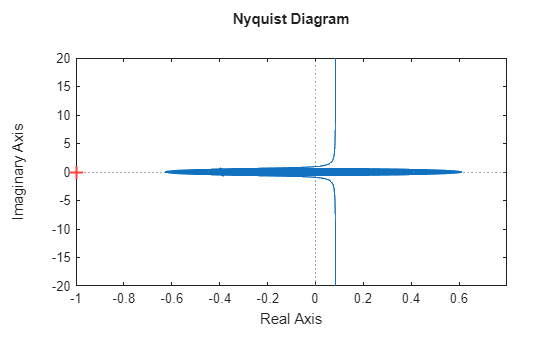

G0=Gr*Gs;
%Darstellung PID Controller in Ideal-Form
figure;
hold off;
nyquist(G0);

disp(Gr);

  pidstd with properties:

              Kp: 2
              Ti: 0.6000
              Td: 0.1500
               N: 100
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



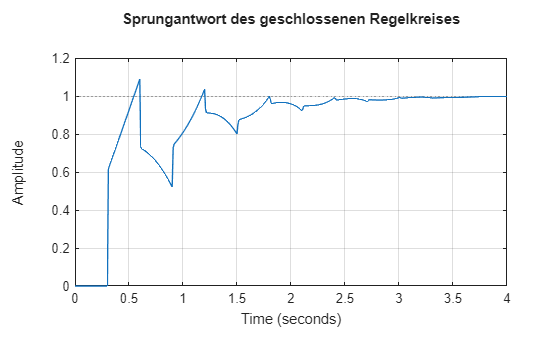


% Optional: Geschlossener Regelkreis (Führungsverhalten)
T_closed = feedback(G0, 1);

% Optional: Sprungantwort des geschlossenen Kreises plotten
step(T_closed);
grid on;
title('Sprungantwort des geschlossenen Regelkreises');

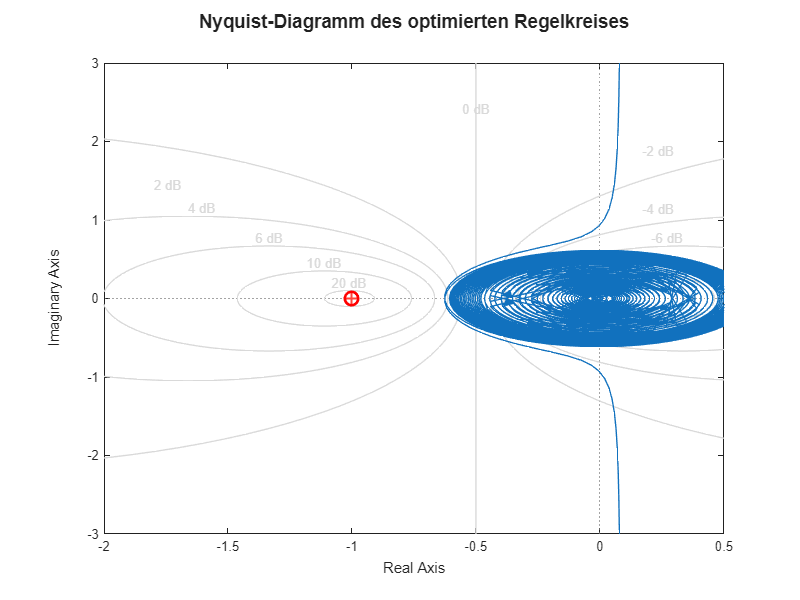


% 4. Schöner, hochauflösender Plot
figure('Position', [100, 100, 800, 600]);
% Definiere einen festen Frequenzvektor von 0.1 rad/s bis z.B. 50 rad/s

% Plotten mit begrenztem Frequenzband
nyquist(G0);
hold on;

% Kritischen Punkt (-1, 0i) fett markieren
plot(-1, 0, 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Kritischer Punkt');

% Achsen-Fokus setzen, damit man das relevante Nyquist-Verhalten sieht!
xlim([-2, 0.5]);
ylim([-3, 3]);

grid on;
grid minor;
title('Nyquist-Diagramm des optimierten Regelkreises', 'FontSize', 14);

### C Einfluss von Stellgrößenbeschränkung

Simulieren Sie eine Stellgrößenbeschränkung für das Regelsystem aus Aufgabe B. Diese kann mit dem Simulink-Block `Saturation` implementiert werden. Die Stellgröße ist zuerst auf das Interval $\left\lbrack -3,3\right\rbrack$ und dann auf das Interval $\left\lbrack -1\ldotp 5,1\ldotp 5\right\rbrack$ zu beschränken. Beschreiben Sie, wie sich die verschiedenen Beschränkungen auf das Verhalten des Regelkreises auswirken. 

### D Einfluss von Störsignal

Simulieren Sie das Einwirken eines Störsignals auf die Stellgröße des Regelkreises aus Aufgabe B (siehe Abbildung). Verwenden Sie als Störfunktion eine verzögerte Sprungfunktion. 

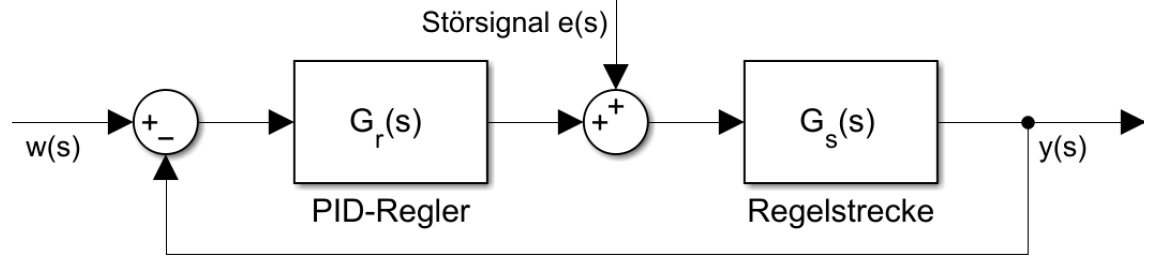

%Versuch Aufsetzen, wichtiges Markieren und daraus Auslesen und
%auszuwerten.

%Störung am Eingang anderes verhalt als störung am Ausgang, der einem
%Sprung gleicht.